## Kalman Filtering Example

clear all

### Define a process model

% Sampling period
Ts = 0.5;

% Discrete-time transfer function
Gpd = tf(0.3, [1 -0.7], Ts);

### Generate some data by simulating the system 

% Number of sample periods
nT = 20;

% Time vector
t = Ts*(0:nT)';

% Input signal
u = zeros(nT+1,1);
u(t>=1) = 1;

[y, t] = lsim(Gpd,u,t);

% Add measurement noise
rng(0);
v = 0.5*randn(nT+1,1);
y_m = y + v;

### Plot simulation results

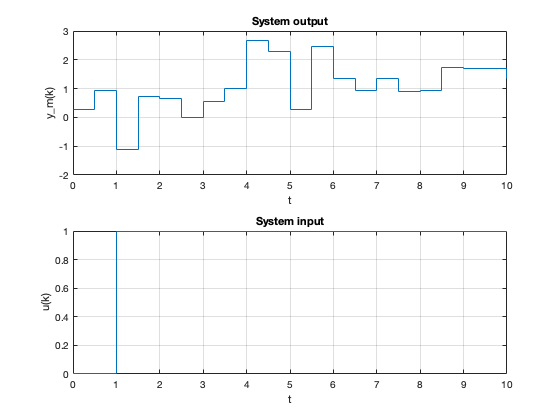

figure(1); clf
subplot(2,1,1)
stairs(t,y_m)
xlabel('t')
ylabel('y_m(k)')
title('System output')
grid on
subplot(2,1,2)
stairs(t,u)
xlabel('t')
ylabel('u(k)')
title('System input')
grid on

## Define observer

% Process model for use by observer
A = 0.7;
B = 1;
C = 0.3;
D = 0;

% Kalman filter parameters
P0 = 1000;
Q = 0.01;
R = 0.5^2;
KF1 = kalman_filter(A,B,C,D,Ts,P0,Q,R,'KF1');

### Simulate observer

% Arrays to store simulation results
yk_est = nan(nT+1,1);
obs = KF1;
yk_est(1,:) = obs.ykp1_est;
for i = 1:nT
    obs = update_KF(obs, u(i), y_m(i));
    yk_est(i+1,:) = obs.ykp1_est;
end

### Compare observer estimates to plant data

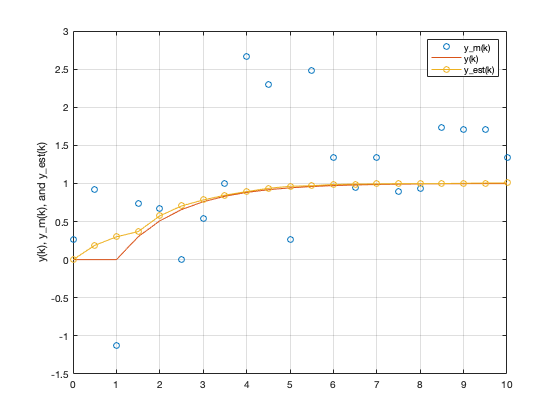

figure(2); clf
plot(t,y_m,'o',t,y,'-',t,yk_est,'o-')
grid on
ylabel('y(k), y_m(k), and y_est(k)')
legend('y_m(k)','y(k)','y_est(k)')

% Display simulation results
table(t,u,y,v,y_m)

ans = 21×5 table
     t     u       y           v           y_m   
    ___    _    _______    _________    _________

      0    0          0      0.26883      0.26883
    0.5    0          0      0.91694      0.91694
      1    1          0      -1.1294      -1.1294
    1.5    1        0.3      0.43109      0.73109
      2    1       0.51      0.15938      0.66938
    2.5    1      0.657     -0.65384    0.0031559
      3    1     0.7599      -0.2168       0.5431
    3.5    1    0.83193      0.17131       1.0032
      4    1    0.88235       1.7892       2.6715
    4.5    1    0.91765       1.3847       2.3024
      5    1    0.94235     -0.67494      0.26741
    5.5    1    0.95965       1.5175       2.4771
      6    1    0.97175       0.3627       1.3345
    6.5    1    0.98023    -0.031527       0.9487
      7    1